# Author: Dan Pollak

Script to organize workspace into appropriate quadrants, do some analysis

clear all
close all

FIMeg = IBWread('8.24.15FICurves.ibw');

IVMilo = 
(:,:,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0   

FIMeg = FIMeg.y;
FIMeg = FIMeg(1:end/2, :, :);%because it doubles it for some reason

FIBeethoven = IBWread('8.26.15FICurves.ibw');
FIBeethoven = FIBeethoven.y;
FIBeethoven = FIBeethoven(1:end/2, :, :);

FIOpus = IBWread('8.27.15FICurves.ibw');
FIOpus = FIOpus.y;
FIOpus = FIOpus(1:end/2, :, :);%because it doubles it for some reason

FIMname = IBWread('9.2.15FICurves.ibw');
FIMname = FIMname.y;
FIMname = FIMname(1:end/2, :, :);%because it doubles it for some reason
FIMname(4,:,:) = 0;

FILincoln = IBWread('9.3.15FICurves.ibw');
FILincoln = FILincoln.y;
FILincoln = FILincoln(1:end/2, :, :);%because it doubles it for some reason

FISelene = IBWread('9.1.15FICurves.ibw');
FISelene = cat(3, FISelene.y, zeros(8,15));
%FISelene = FISelene(1:end/2, :, :);%because it doubles it for some reason

FIgroup1males = [FIBeethoven; FIOpus];
FIgroup2males = [FIMname; FILincoln];
FImales = [FIgroup1males; FIgroup2males];

FIgroup1females = [FISelene];
FIgroup2females = [FIMeg];
FIfemales = [FIgroup1females; FIgroup2females];

FIgroup1 = [FIgroup1females; FIgroup1males];
FIgroup2 = [FIgroup2females; FIgroup2males];

%IV

IVMeg = IBWread('8.24.15IVCurves.ibw');
IVMeg = IVMeg.y;
IVMeg = IVMeg(1:end/2, :, :);%because it doubles it for some reason

IVBeethoven = IBWread('8.26.15IVCurves.ibw');
IVBeethoven = IVBeethoven.y;
IVBeethoven = IVBeethoven(1:end/2, :, :);%because it doubles it for some reason

IVOpus = IBWread('8.27.15IVCurves.ibw');
IVOpus = IVOpus.y;
IVOpus = IVOpus(1:end/2, :, :);%because it doubles it for some reason

IVMname = IBWread('9.2.15IVCurves.ibw');
IVMname = IVMname.y;
IVMname = IVMname(1:end/2, :, :);%because it doubles it for some reason
IVMname(4,:,:) = 0;%EXCISING BAD DATA, will turn to Nan's later

IVLincoln = IBWread('9.3.15IVCurves.ibw');
IVLincoln = IVLincoln.y;
IVLincoln = IVLincoln(1:end/2, :, :);%because it doubles it for some reason

IVSelene = IBWread('9.1.15IVCurves.ibw');
IVSelene = cat(3, IVSelene.y, zeros(8,15));
IVSelene = IVSelene(1:end/2, :, :);%because it doesnt double it for some reason

IVgroup1males = [IVBeethoven; IVOpus];
IVgroup2males = [IVMname; IVLincoln];
IVmales = [IVgroup1males; IVgroup2males];

IVgroup1females = [IVSelene];
IVgroup2females = IVMeg;
IVfemales = [IVgroup1females; IVgroup2females];

IVgroup1 = [IVgroup1females; IVgroup1males];
IVgroup2 = [IVgroup2females; IVgroup2males];

## Here's what happened so far

I concatenated the matrices vertically. Right now, the vectors I want to

use are sideways. So in the partition below, I will correct this with the

' operator.

## Graphing. Just change the FOUR fields noted below.

%Note: passive properties are usually resistance, and that is iv
temp = FIMilo;%%CHANGE HERE 1
toGraph2 = FIMilo;%%CHANGE HERE 2
name  = 'FI Milo ';%%CHANGE HERE 3
name2 = 'FI Milo';%%CHANGE HERE 4
bothNames = strcat(name, ' and ', name2);

toGraph = temp;%b/c we need to reset it at some point

xAxis = -50:10:90;
toGraph = mean(toGraph, 3);
toGraph2 = mean(toGraph2, 3);
%excising zero rows
toGraph( ~any(toGraph,2), : ) = [];
toGraph2( ~any(toGraph2,2), : ) = [];

% 1 2 3 4 -> -5, -4, -3,-2,-1-> -50, -40, -30, -20, -10
[~, Q] = max(toGraph, [], 2); 
figure;
h1 = plot(xAxis, toGraph', 'LineWidth', 1.25, 'Color', 'b');

Error using plot
Vectors must be the same length.


hold on;
title(bothNames);
h2 = plot(xAxis, toGraph2, 'LineWidth', 1.25, 'Color', 'r')
ax = gca;
ax.XTick = -50:10:90;
ax.XTickLabelRotation = 45;
% some ugly stuff to get legend to do what I want
legend([plot(1, 'Color', 'b') plot(1, 'Color', 'r')],'group 1','group 2','Location', 'Best');

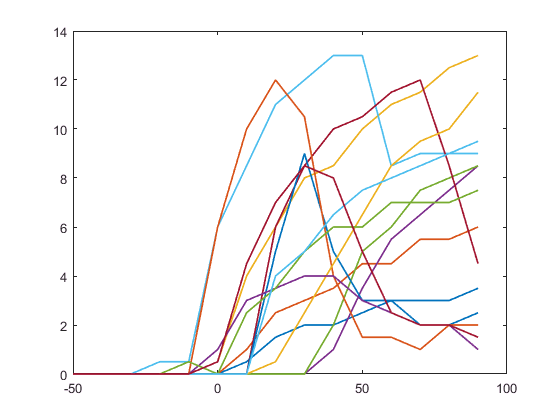

figure;
handle = plot(xAxis, toGraph2(:, 1:Q)', 'LineWidth', 1.25);
hold on;

title(name);

Undefined function or variable 'name1'.


ax = gca;
ax.XTick = -50:10:90;
ax.XTickLabelRotation = 45;
legend(handle, num2str((1:numel(toGraph2(:,1,1)))'),'Location', 'Best');
figure;
handle = plot(xAxis, toGraph2(:, 1:Q)', 'LineWidth', 1.25);
hold on;
title(name2);
ax = gca;
ax.XTick = -50:10:90;
ax.XTickLabelRotation = 45;
legend(handle, num2str((1:numel(toGraph2(:,1,1)))'),'Location', 'Best');

## IV curves with error bars

if(strfind(name, 'IV') ~= 0)
    ylabel('mV')
    xlabel('pA')
    ax.YTick = -1.2:0.01:0;
    ylim([-.12, 0])
    sem = std(toGraph)/sqrt(length(toGraph(:,1,1)));
    toGraph = mean(toGraph(~all(toGraph==0,2),:)); % changing toGraph further, compressing it to one row from two dimensions
    errorbar(xAxis, toGraph, sem, 'color', 'b');
    savefig(strcat(bothNames, 'WithErrorBars.fig'));
end

## FI curves with error bars

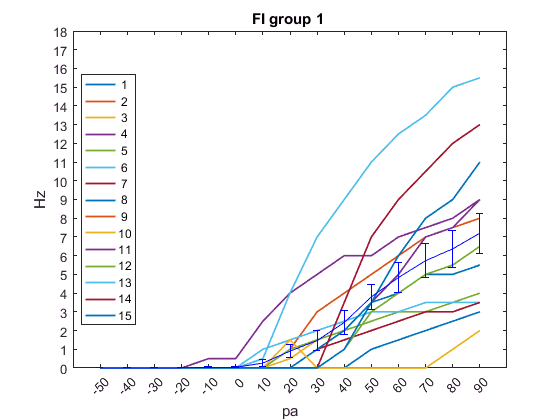

if(strfind(name, 'FI') ~= 0)
    % plain old FI curves
    ylabel('Hz')
    xlabel('pa')
    ax.YTick = 0:18;
    ylim([0, 18])
    sem = std(toGraph)/sqrt(length(toGraph(:,1,1)));
    toGraph = mean(toGraph);%changing toGraph further, compressing it to one row
    errorbar(xAxis, toGraph, sem, 'color', 'b');
    savefig(strcat(bothNames, 'WithErrorBars.fig'));
    %FI curve slopes in bar graph
end

## Beeswarm + bar graph + error bars

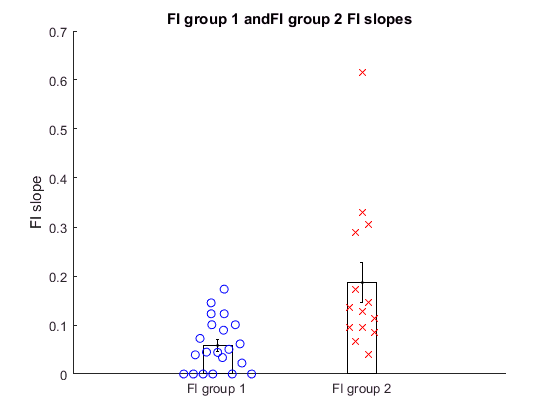

if(strfind(name, 'FI') ~= 0) % m = (y2 - y1)/(x2 - x1)
    toGraph = temp;
    toGraph = mean(toGraph, 3);
    
    [maxi, I] = max(toGraph, [], 2); % 1 2 3 4 -> -5, -4, -3,-2,-1-> -50, -40, -30, -20, -10
    [maxi2, I2] = max(toGraph2, [], 2);
    I = (I-6)*10; % array of indices
    I2 = (I2-6)*10;
    aMs = (maxi - 0)./(I-toGraph(find(toGraph, 1)));
    aMs2 = (maxi2 - 0)./(I2-toGraph2(find(toGraph2, 1)));
    
    figure;
    hold on;
    sem = std(aMs)/sqrt(length(aMs));
    sem2 = std(aMs2)/sqrt(length(aMs2));
    bar(1:2, [mean(aMs) mean(aMs2)], .2, 'FaceColor', [1, 1, 1]);
    errorbar(1:2, [mean(aMs) mean(aMs2)], [sem sem2], '.', 'color',...
        'k')
    
    plotSpread({aMs, aMs2},'xNames', {name, name2}, ... 
        'distributionMarkers', {'o','x'}, 'distributionColors',{'b','r'})
    title(strcat(bothNames, ' FI slopes'))
    xlim([0, 3])
    ylabel('FI slope')
    savefig(strcat(bothNames, 'FISlopeBarAndBeeswarmfig'));
end

## Standard Error Graphs IV and FI

Standalone line graphs with error bars

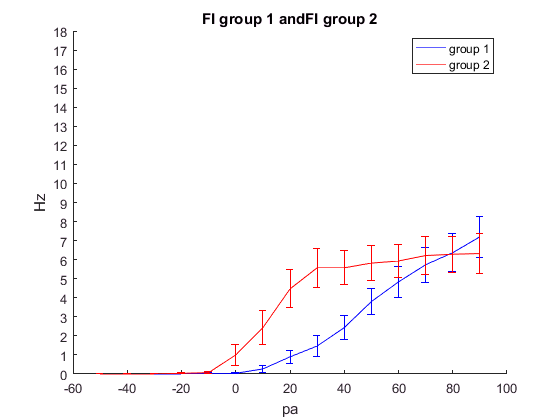

%reset toGraph
toGraph = mean(temp, 3);

%excising zero rows
toGraph( ~any(toGraph,2), : ) = [];
toGraph2( ~any(toGraph2,2), : ) = [];

excel1 = toGraph;
excel2 = toGraph2;

handle = figure; 
ax = gca;
hold on;
title(bothNames);
if(strfind(name, 'IV') ~= 0)
    ylabel('mV')
    xlabel('pA')
    ax.YTick = -1.2:0.01:0;
    ylim([-.12, 0])
    sem = std(toGraph)/sqrt(length(toGraph(:,1,1)));
    sem2 = std(toGraph2)/sqrt(length(toGraph2(:,1,1)));   
    toGraph = mean(toGraph(~all(toGraph==0,2),:)); % making toGraph one row
    toGraph2 = mean(toGraph2(~all(toGraph2==0,2),:));
    errorbar(xAxis, toGraph, sem, 'color', 'b'); % now xAxis, toGraph, and sem are all same size
    errorbar(xAxis, toGraph2, sem2, 'color', 'r');
    savefig(strcat(bothNames, 'OnlyErrorBar.fig'));
elseif(strfind(name, 'FI') ~= 0)
    ylabel('Hz')
    xlabel('pa')
    ax.YTick = 0:18;
    ylim([0, 18])
    sem = std(toGraph)/sqrt(length(toGraph(:,1,1)));
    sem2 = std(toGraph2)/sqrt(length(toGraph2(:,1,1)));   
    toGraph = mean(toGraph(~all(toGraph==0,2),:));
    toGraph2 = mean(toGraph2(~all(toGraph2==0,2),:));
    errorbar(xAxis, toGraph, sem, 'color', 'b');
    errorbar(xAxis, toGraph2, sem2, 'color', 'r');
    savefig(strcat(bothNames, 'OnlyErrorBar.fig'));
    legend('group 1','group 2','Location', 'Best');
end